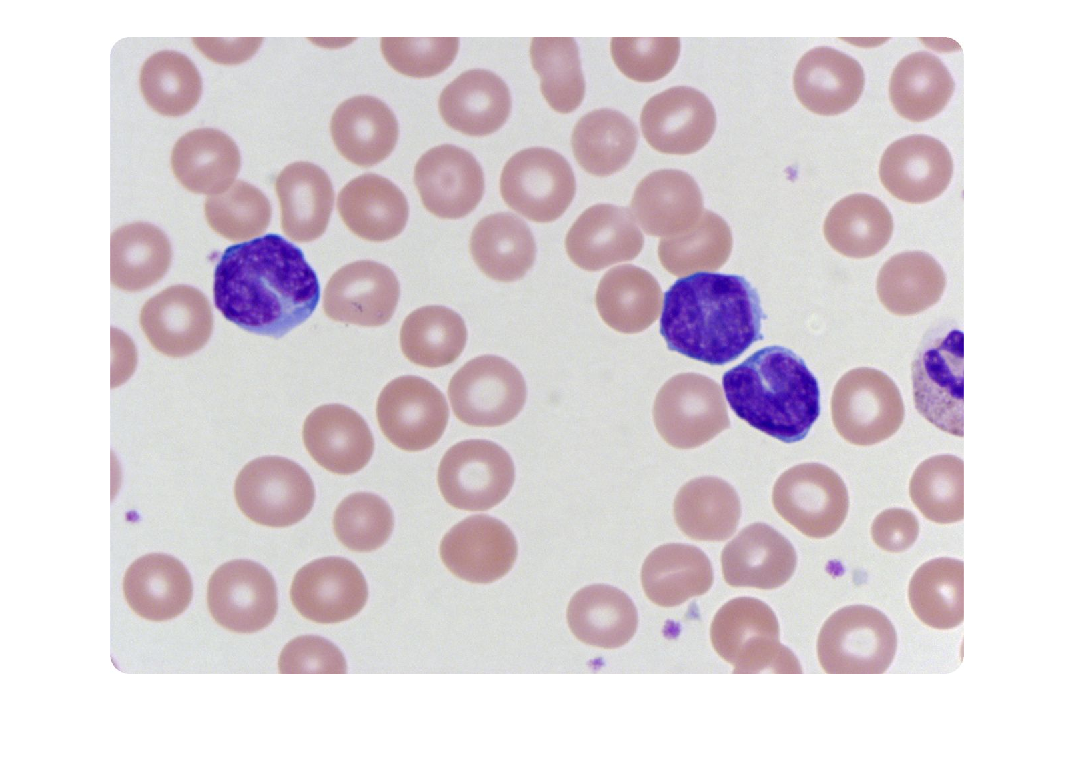

rgb = imread('F1.jpg');
figure
imshow(rgb)

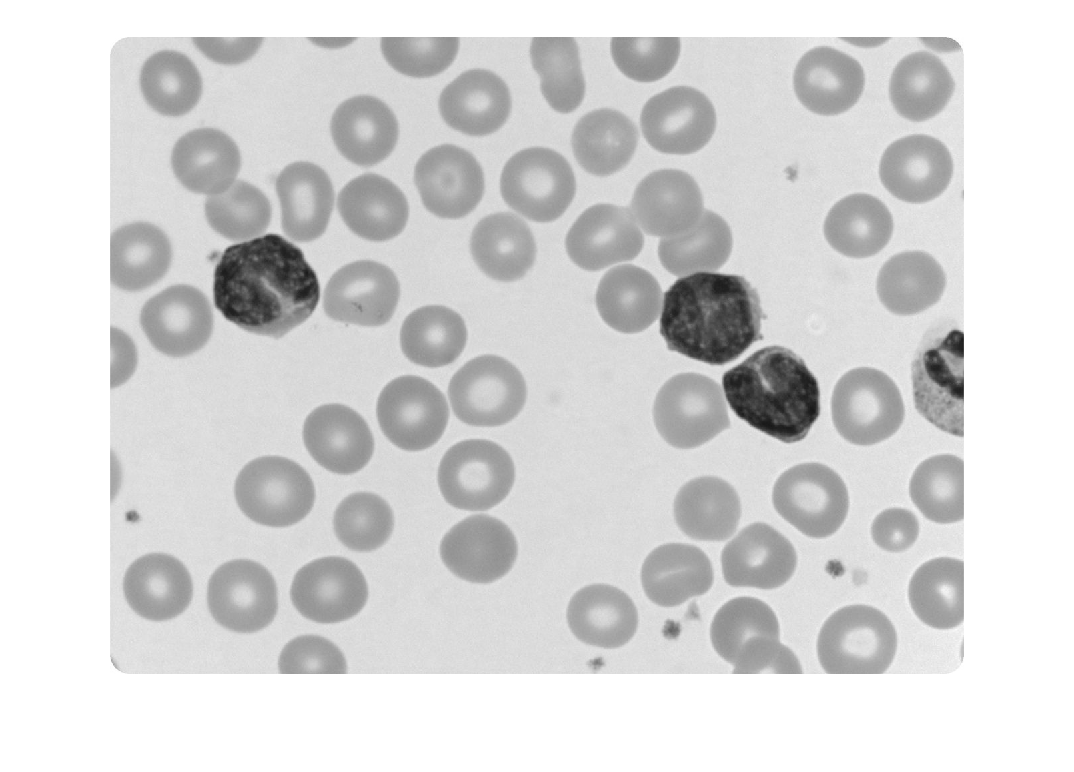


gray_image = rgb2gray(rgb);
imshow(gray_image);


[centers, radii] = imfindcircles(rgb,[35 60],'ObjectPolarity','dark','Sensitivity',0.9)

centers = 	1.0e+03 *

    0.0726    0.8253
    0.3804    0.7271
    1.1234    0.2837
    0.4527    0.5638
    0.4853    0.4493
    0.9523    0.8911
    0.7780    0.3931
    1.2094    0.1981
    1.0766    0.0664
    0.8035    0.0167


radii =    51.1986
   45.0988
   49.5974
   54.9539
   48.7702
   51.6984
   50.2274
   53.2379
   52.6792
   51.3415


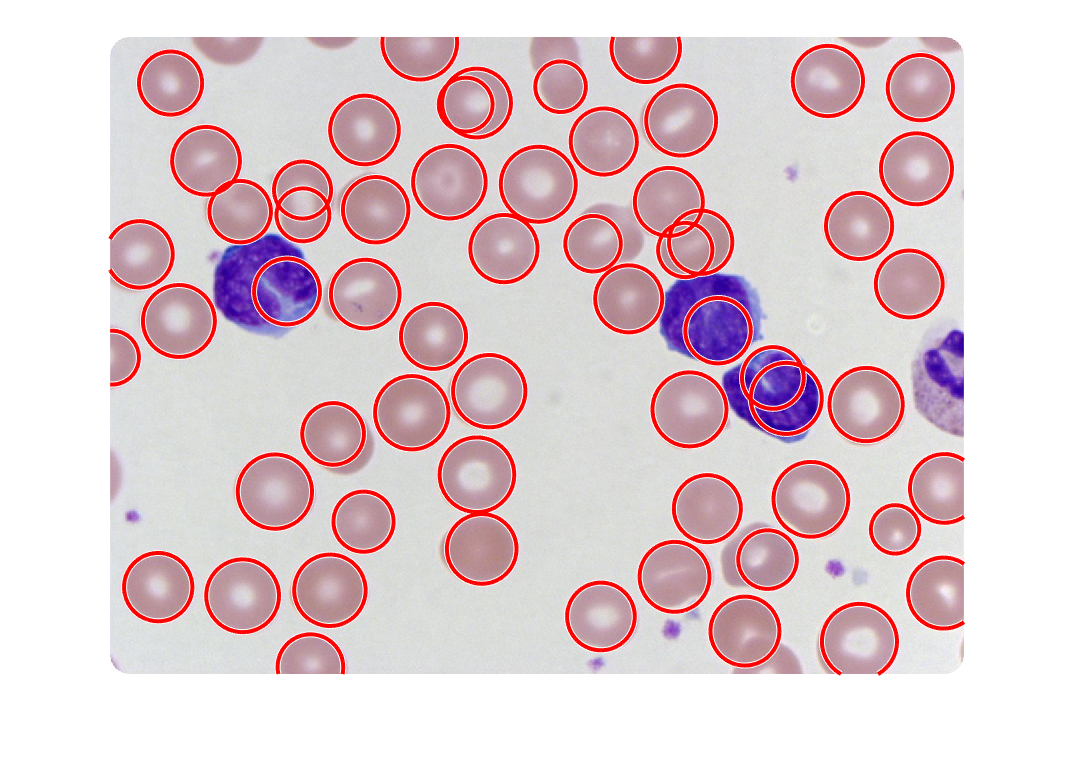

h =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


imshow(rgb);

h = viscircles(centers,radii)

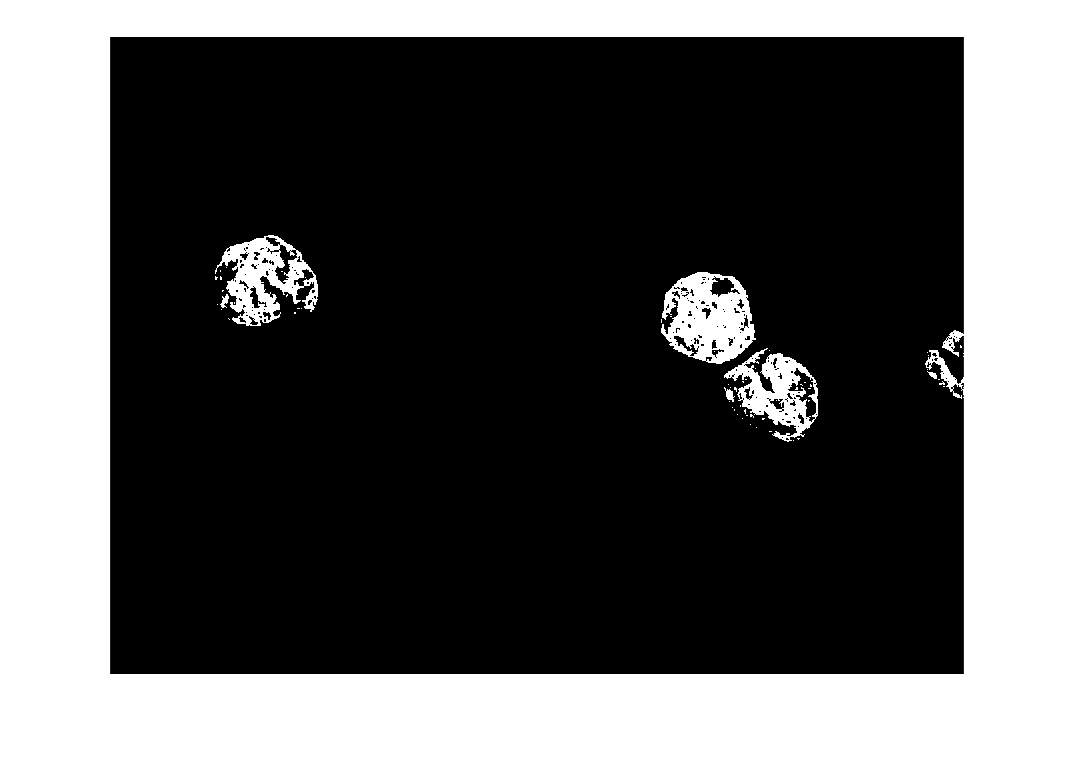

cell=length(centers);

red=rgb(:,:,1);green= rgb(:,:,2); blue= rgb(:,:,3);
%p=impixel(rgb);
out=red>25 & red<123 &green<135 & blue>167 & blue<201;
imshow(out);

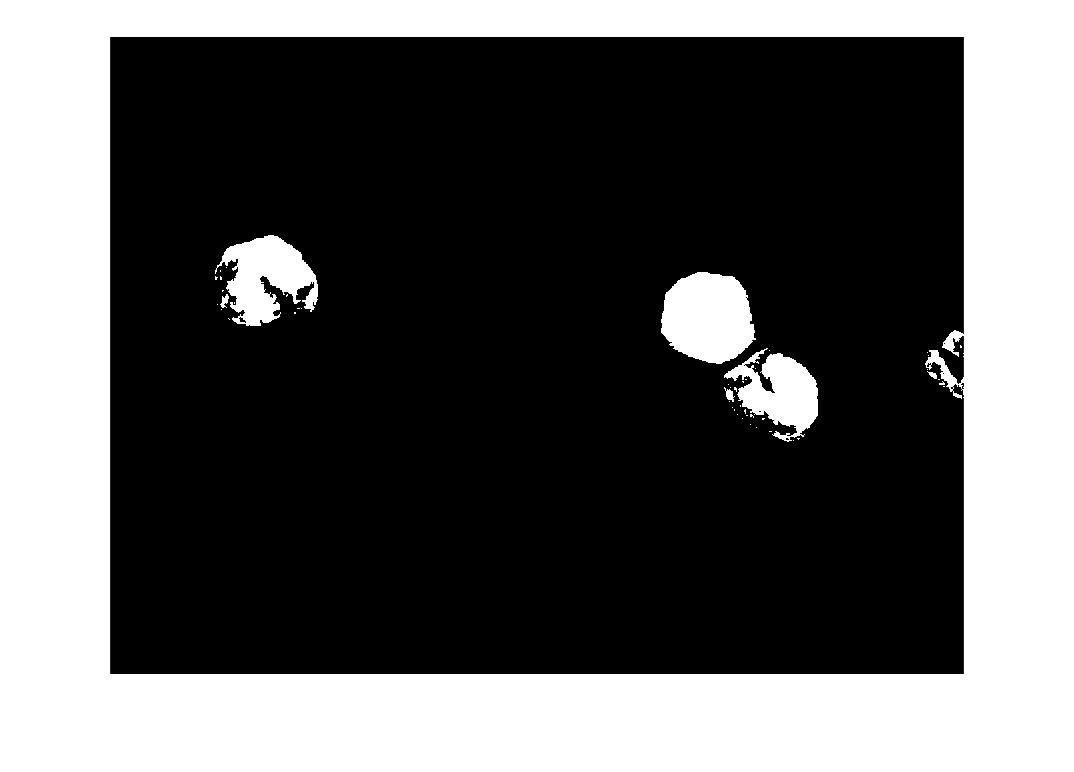


out1=imfill(out,'holes');
imshow(out1);

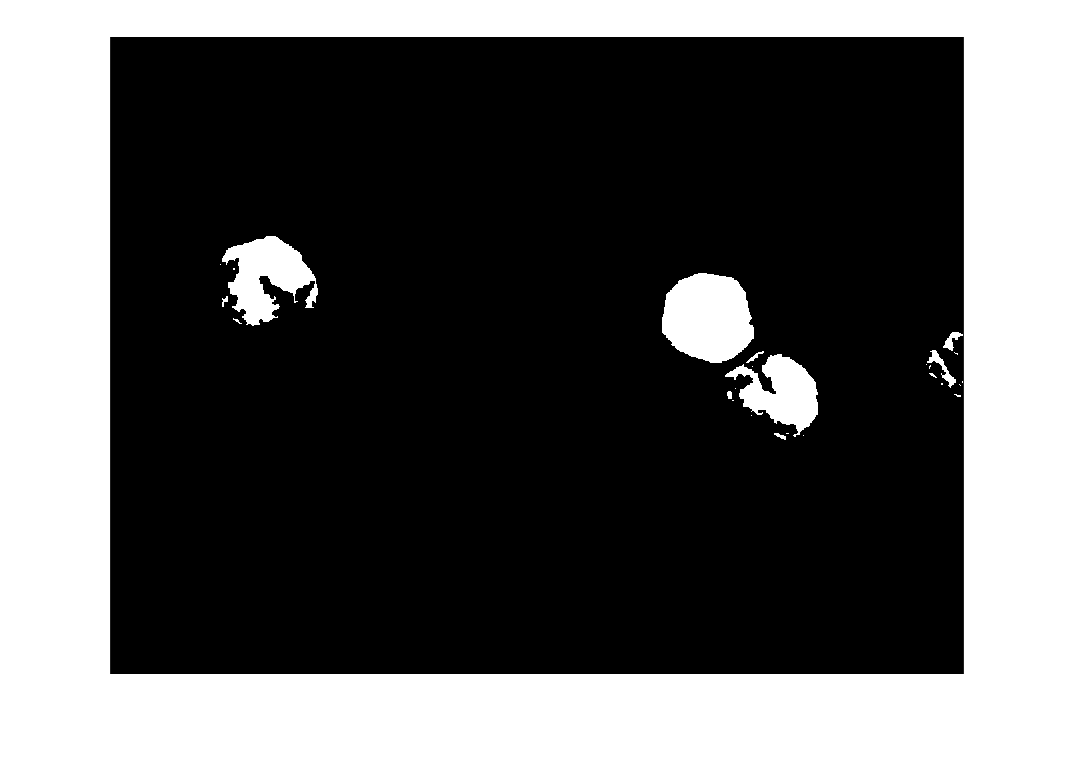

out2=bwmorph(out1,'erode');
imshow(out2);

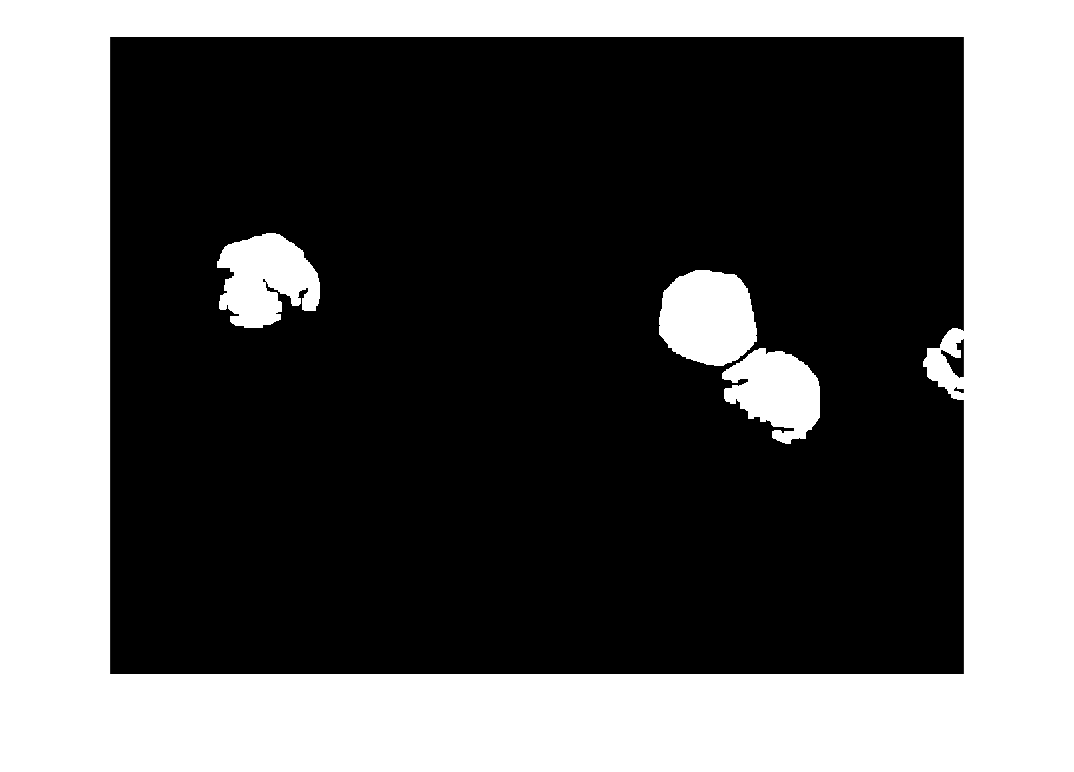


out3=bwmorph(out2,'dilate',4);
out3=imfill(out3,'holes');
imshow(out3);

out3=im2bw(out3);

[l,NUM]=bwlabel(out3,4);
cancer=(NUM/cell)*100;
if cancer<25 
    disp('initial stage');
    disp('cnacer persentage is')
    disp(cancer);
end

initial stage


cnacer persentage is


    6.7797

